## 1.7绘制GIF动态图

基本思想：先生成多张静态图片，在组合成gif

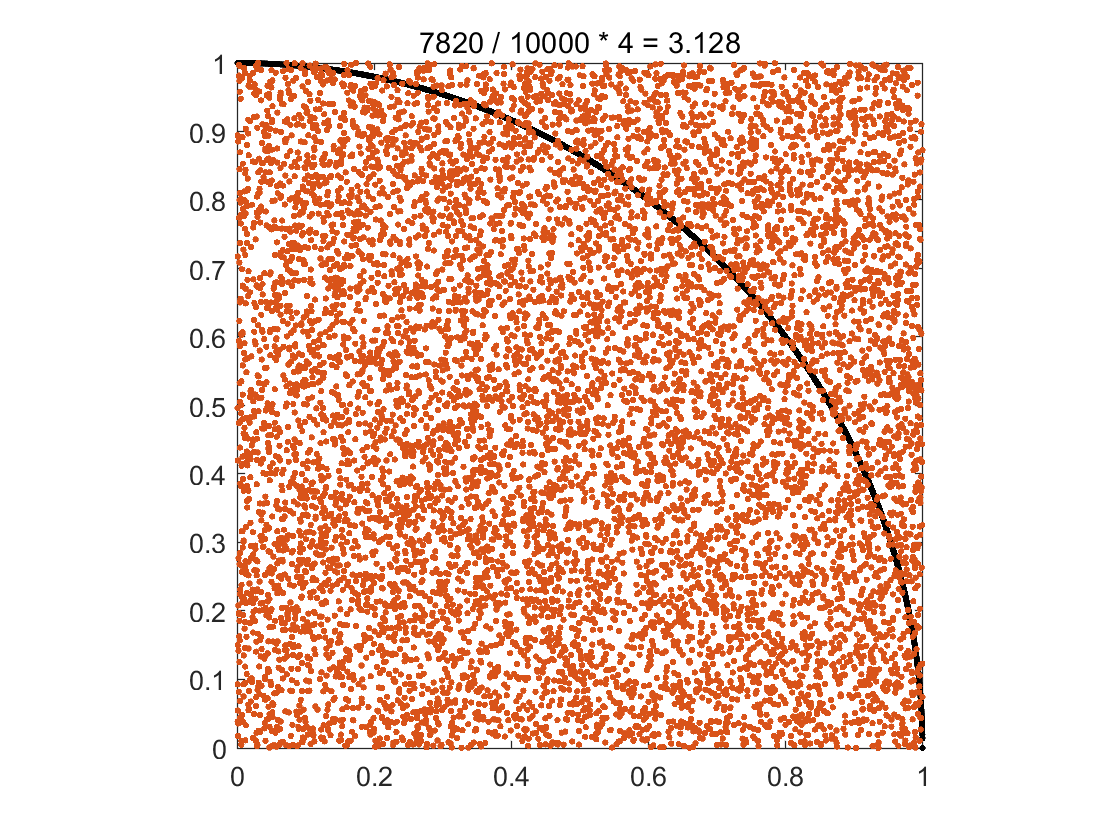

for i = [500,1000,2000,5000,10000]
    x1 = linspace(0,1,10000);
    y1 = sqrt(1-x1.^2);

    x2 = rand([1,i]);
    y2 = rand([1,i]);

    count = 0;
    for j = 1:i
        if (x2(j)^2 + y2(j)^2) < 1
            count = count + 1;
        end
    end

    plot(x1,y1,'k .',x2,y2,"."); axis square;
    title(num2str(count)+" / "+num2str(i)+" * 4 = "+num2str(count/i*4));
    
    frame = getframe(gcf);
    I = frame2im(frame);
    [I,map] = rgb2ind(I,256);
    
    if i == 500
        imwrite(I,map,'test.gif','gif','LoopCount',inf,'DelayTime',0.5);
    else
        imwrite(I,map,'test.gif','gif','WriteMode','append','DelayTime',0.5);
    end

end